% E9.2
clear all
s = tf('s');

K = 4;
% 문제상에는 Ls = K*(1+s/20)/(s*(1+s/8)*(1+s+10)) 로 되어있지만,
% 주어진 교차주파수와 위상여유를 보았을 때 Ls = K*(1+s/20)/(s*(1+s/8)*(1+s+10))로
% 하는것이 맞다.
Ls = K*(1+s/20)/(s*(1+s/8)*(1+s/10))

Ls =
 
        320 s + 6400
  -------------------------
  20 s^3 + 360 s^2 + 1600 s
 
연속시간 전달 함수입니다.
모델 속성


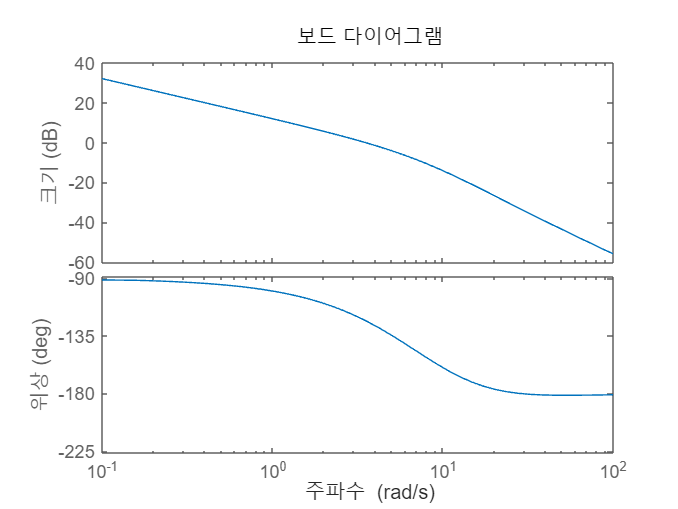

sys = Ls;
bode(sys);

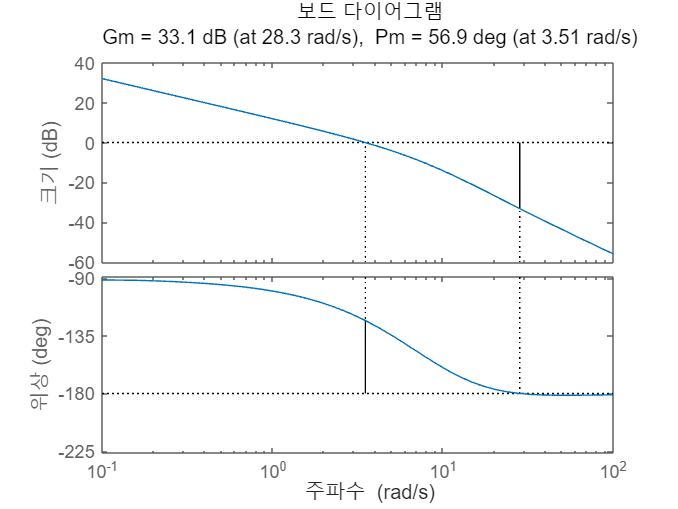

margin(sys);

[Gm, Pm, Wcg, Wcp] = margin(sys);
Gm = mag2db(Gm);
Pm;
fprintf("P.M. = %.1f[°]\n", Pm)

P.M. = 56.9[°]


fprintf("Wcp(위상여유의 교차주파수) = %.2f[rad/s]\n", Wcp)

Wcp(위상여유의 교차주파수) = 3.51[rad/s]
